1. Present the mathematical explanation of eigenfaces, including how to generate the eigenfaces from the data set.

An eigenface is the measure of the variability between images in a larger set of images. In other words, its a measure of how close a face is to the average face of every face in the set of images. To generate the eigenfaces for the given data set first the images need to be converted into matricies. This can be done by reading the pgm images and converting them into double values, giving a 192x168 matrix for each face. To then calculate the mean face all the columns will be averaged and combined into one mean face matrix. Then mean centering the faces, by subtracting each column of each face in the set from this mean face, the new matricies is a measure of how each face differes from the mean face. Then by simply using singular value decomposition, the eigenvalues of each mean centered face is the eigenface.

The following code extracts the first 20 eigenfaces from the data set.

2. Implement code in MATLAB to produce the mean face and eigenfaces figures from the Background Reading document.

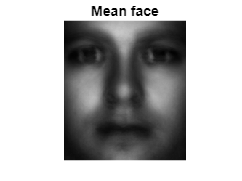

d = dir('faces/*.pgm');
for i = 1:length(d)
    % load in 192x168 matrix representing face
    I(:, :, i) = imread(['faces/', d(i).name]);

    % convert from uint8 to double
    I(:, :, i) = double(I(:, :, i)) / 255; 

    % mean face
    I_m = mean(I, 3);

    % subtract from mean face
    I_c(:, :, i) = double(I(:, :, i)) - I_m;

    % Reduced SVD: U has the same size as A; Sigma and V are square
    [U(:, :, i),Sigma,V] = svd(I_c(:, :, i), 'econ');
    U_image(:, :, i) = uint8(U(:, :, i));
end


figure(1)
imshow(I_m, 'initialmagnification', 'fit')
title('Mean face')

## Eigen Faces

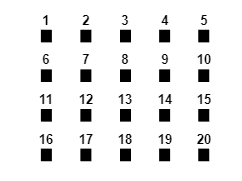

figure(2)
for i = 1:20
    subplot(4, 5, i)
    imshow(U_image(:, :, i), 'initialmagnification', 'fit')
    title((i))
end